### Question 1:

The state vector is defined as:


$$x=\left[\begin{array}{c}
x_1\\
x_2\\
x_3\\
\end{array}\right]=
\left[\begin{array}{c}
\alpha\\
q\\
\theta\\
\end{array}\right]$$



$$u=\delta$$



$$\dot{x_1}=\dot{\alpha}=-0.313\alpha+56.7q+0.232\delta\\
\dot{x_2}=\dot{q}=-0.0139\alpha-0.426q+0.0203\delta\\
\dot{x_3}=\dot{\theta}=q$$


The continuous-time state-space matrices are


$$A=\left[\begin{array}{ccc}
-0.313 & 56.7 & 0\\
-0.0139 & -0.426 & 0\\
0 & 1 & 0\\
\end{array}\right]x+
\left[\begin{array}{c}
0.232\\
0.0232\\
0\\
\end{array}\right]u
\\
y=\left[\begin{array}{ccc}
0 & 0 & 1\\\end{array}\right]x+0\times u$$


A=  [-0.313 56.7 0
    -0.0139 -0.426 0
    0 1 0];
B=  [0.232
    0.0203
    0];
C = [0 0 1];
D = 0;

% Build a continuous-time state-space model
sys_ss = ss(A, B, C, D);
% Convert to a transfer function
G = tf(sys_ss)


G =
 
     0.0203 s + 0.003129
  --------------------------
  s^3 + 0.739 s^2 + 0.9215 s
 
Continuous-time transfer function.
Model Properties


### Question 2:

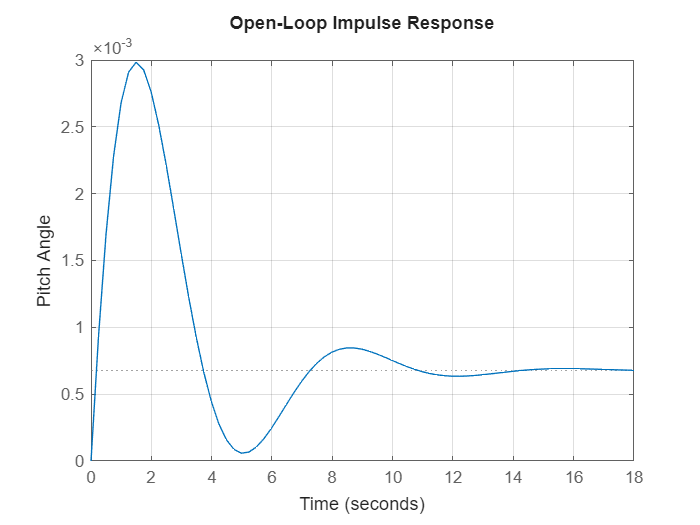

% Define state-space matrices
A = [ -0.313   56.7     0
      -0.0139  -0.426   0
       0        1       0 ];

B = [ 0.232
      0.0203
      0     ];

C = [ 0  0  1 ];
D = 0;

% Create state-space system
sys_ss = ss(A, B, C, D);

% Convert state-space to transfer function
G = tf(sys_ss);

% Impulse response with amplitude scaling (0.2)
impulse(0.2 * G);
title('Open-Loop Impulse Response');
xlabel('Time');
ylabel('Pitch Angle');
grid on;

### Question 3:

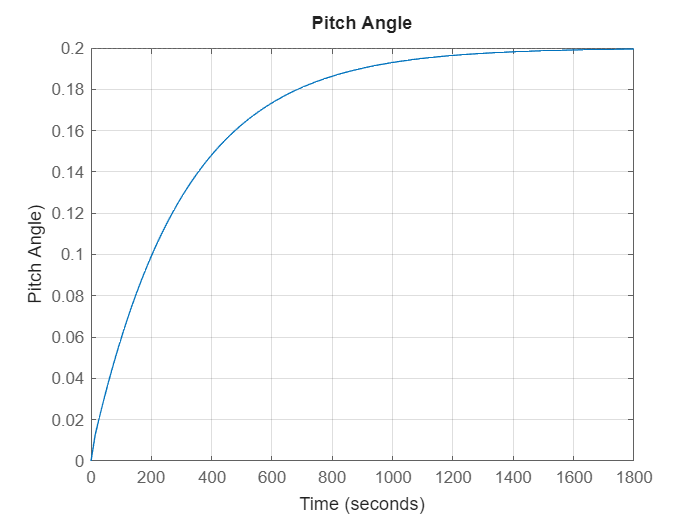

% System Matrices
A = [ -0.313   56.7    0
      -0.0139  -0.426  0
       0        1      0 ];
B = [ 0.232
      0.0203
      0      ];
C = [ 0  0  1 ];
D = 0;

% Create continuous-time state-space system
sys_ss = ss(A, B, C, D);

% Open-Loop Transfer Function
G = tf(sys_ss);

% Controller: C(s) = K = 1 (Proportional Gain)
K = 1;

% Closed-Loop System with Unity Feedback
G_cl = feedback(K * G, 1);

% Step Response with a 0.2 rad Reference (Pitch Angle)
step(0.2 * G_cl);
title('Pitch Angle');
xlabel('Time');
ylabel('Pitch Angle)');
grid on;

### Question 4:

% Continuous-time model (A, B, C, D)
A = [ -0.313   56.7     0
      -0.0139  -0.426   0
       0        1       0 ];
B = [ 0.232
      0.0203
      0      ];
C = [ 0  0  1 ];
D = 0;

% Build the continuous-time state-space model
sys_ss = ss(A, B, C, D);

% Convert to transfer function (for reference, if needed)
G = tf(sys_ss);

% Discretize using zero-order hold
Ts = 0.02;  % Sampling period
sys_d = c2d(sys_ss, Ts, 'zoh');
Gd = c2d(G, Ts, 'zoh');

% Extract the discrete-time state-space matrices
[Ad, Bd, Cd, Dd] = ssdata(sys_d);

% Construct and display the controllability matrix
Co = ctrb(Ad, Bd);
r = rank(Co);
n = size(Ad, 1);

fprintf('Rank of controllability matrix: %d\n', r);

Rank of controllability matrix: 3


fprintf('Number of states: %d\n', n);

Number of states: 3



if r == n
    disp('Discrete-time system is fully controllable.');
else
    disp('Discrete-time system is NOT fully controllable.');
end

Discrete-time system is fully controllable.
